dataSend = "1010001";
[idealSignal, noisySignal, discretizedSignal, ADCsignal, ADCpreambule, signalSNR] = GenerateSignal(dataSend, 1);

plot(ADCsignal)
load 'FiltroKoef.mat';
fdiskret = 10E6;
tdiskret = 1/fdiskret;
A = 1;
tprescaler = 10;
    
idealOne = A*[ones(1, round(0.5E-6/tdiskret*tprescaler)), zeros(1, round(0.5E-6/tdiskret*tprescaler))];
idealZero = A*[zeros(1, round(0.5E-6/tdiskret*tprescaler)), ones(1, round(0.5E-6/tdiskret*tprescaler))]; %100ilgis

idealPreambule = A*[ones(1, round(0.5E-6/tdiskret*tprescaler)), zeros(1, round(0.5E-6/tdiskret*tprescaler)), ones(1, round(0.5E-6/tdiskret*tprescaler)), zeros(1, round(2E-6/tdiskret*tprescaler)), ones(1, round(0.5E-6/tdiskret*tprescaler)), zeros(1, round(0.5E-6/tdiskret*tprescaler)), ones(1, round(0.5E-6/tdiskret*tprescaler))];
idealPreambule = [idealPreambule, zeros(1, 50)];
nufiltruotaPreambule = filter(Hd, idealPreambule);
plot(nufiltruotaPreambule)

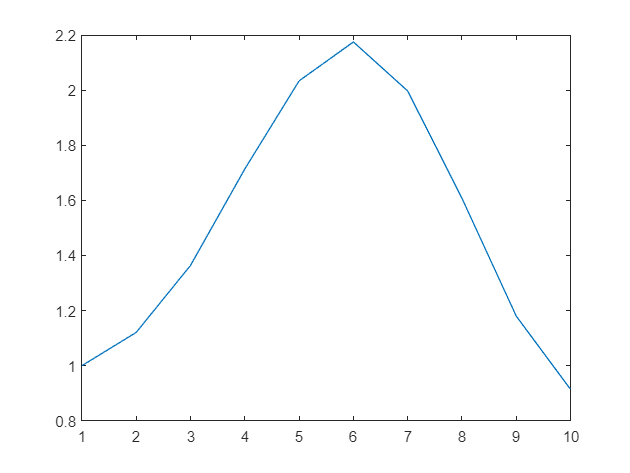


dataSend = "1010001";
[idealSignal, noisySignal, discretizedSignal, ADCsignal, ADCpreambule, signalSNR] = GenerateSignal(dataSend, 1);

impulsas = [zeros(1, 50), ones(1, 50), zeros(1, 50)];
load 'FiltroKoef.mat';
nufiltruotasImpulsas = filter(Hd, impulsas);

nufiltruotasImpulsas = nufiltruotasImpulsas(50:140);
nufiltruotasImpulsas = nufiltruotasImpulsas(1:10:length(nufiltruotasImpulsas))+1;

plot(nufiltruotasImpulsas)

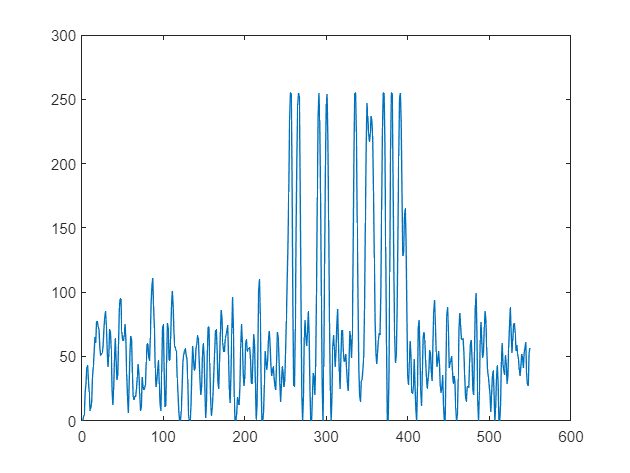


plot(ADCsignal)

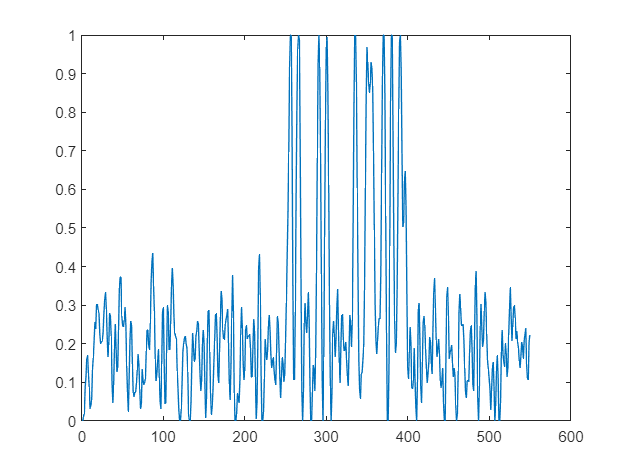

maksimali = max(ADCsignal);
plot(ADCsignal/maksimali)

mean(ADCsignal/maksimali)

ans = 0.2491

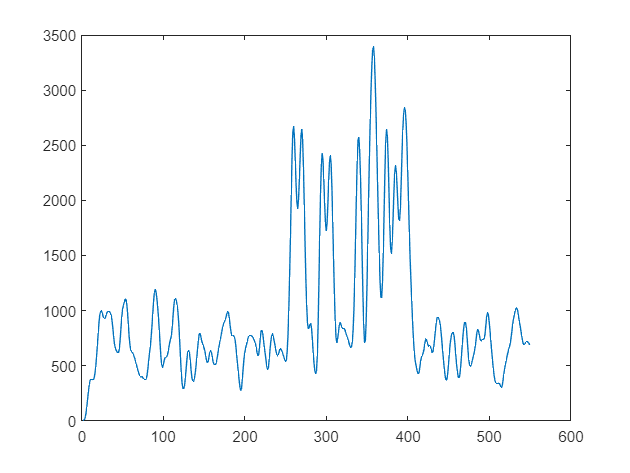


y = GenerateConv(ADCsignal, nufiltruotasImpulsas);

plot(y)

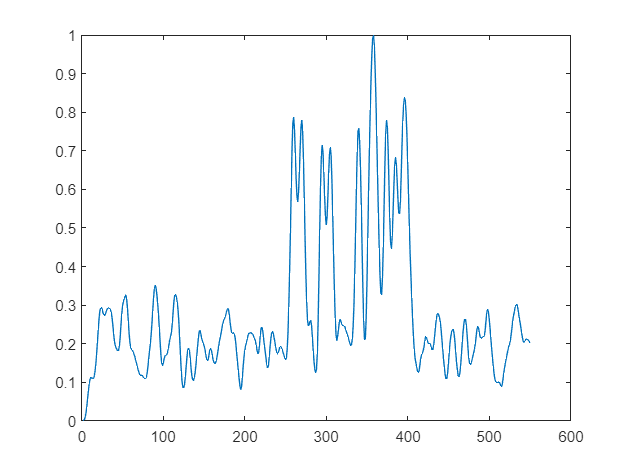

maksimali = max(y);
plot(y/maksimali)

mean(y/maksimali)

ans = 0.2811